# Statistical Analysis - Part I

This lecture will cover several of the statistical analysis tools in MATLAB. 

## Correlation - two variables

Helps identify if a linear relationship exists between two variables

Different types of correlation - Pearson's and Spearman (rank)

- **Pearson's** - measures the strength and direction of a linear relationship between two variables

- **Spearman** - measures the strength and direction of a monotonic relationship between two variables

Both of these measures of correlation are on a scale of -1 to 1.

Consider the two arrays, *A* and *B*: 

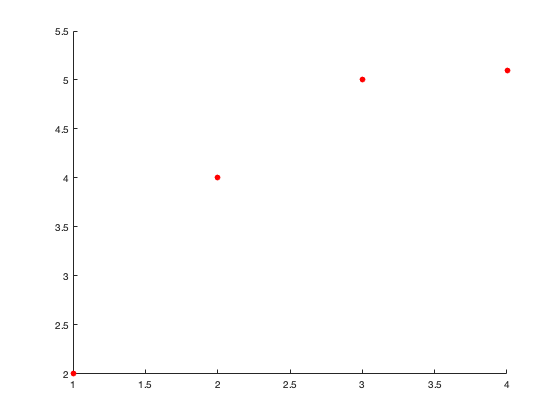

A = [1, 2, 3, 4];
B = [2, 4, 5, 5.1];

scatter(A,B,'red','filled')

r = 0.9244

Based on the above plot, what values would you guess for the Pearson's and Spearman correlation estimates?

We can use the `corr `function, which outputs the pairwise correlation between the columns of the two matrices. With the `corr` function, we have the option to specify Pearson or Spearman correlation by using the `'type' `option. Note that we have to transpose the arrays in order to arrange the data into columns.

r = corr(A',B',"type","Pearson")


r_spear = 1

r_spear = corr(A',B',"type","Spearman")

r_squared = 0.8545

As expected, the Pearson correlation value is fairly high as the two variables appear to have a strong linear relationship.

The output of 1 for the Spearman correlation also makes sense because the two arrays are completely monotonic, meaning that as one variable increases, so does the other. 

Once we have *r, *we can easily calculate the coefficient of determination, $r^2 

$. The coefficient of determination measures the proportion of variance in the dependent variable that can be explained by the independent variable. 

r_squared = r^2

## Correlation - Multiple Variables

We can also examine the correlation between more than two variables. Load the Framingham data set for use in the following examples.

fram = readtable("../frmgham.xls");

ans = 0.7116

Use the `corr` function to find the correlation between systolic and diastolic blood pressure. Note that the default correlation type for `corr` is `"Pearson"`.

corr(fram.SYSBP, fram.DIABP)

ans =     1.0000    0.7116    0.3890
    0.7116    1.0000    0.0693
    0.3890    0.0693    1.0000


When the `corr` function is used on more than two variables, the output is a matrix of the correlation coefficients. Find the correlation between systolic blood pressure, diastolic blood pressure, and age.

corr([fram.SYSBP, fram.DIABP, fram.AGE])

Each value in the matrix corresponds to the correlation between the variables in that particular row and column. For example, the correlation between diastolic blood pressure and age is 0.0693.

This same process can be used for any number of variables. We will now analyze the variables in columns 2 thru 11 of the Framingham data set. First, extract these columns from the full data set.

fram_2_11 = fram(:,2:11);

What variables are included in these ten columns?

var_names = fram_2_11.Properties.VariableNames;

ans = 10×1 cell array
    {'SEX'     }
    {'TOTCHOL' }
    {'AGE'     }
    {'SYSBP'   }
    {'DIABP'   }
    {'CURSMOKE'}
    {'CIGPDAY' }
    {'BMI'     }
    {'DIABETES'}
    {'BPMEDS'  }


var_names' 

In order for the `corr `function to work correctly, we need to remove the observations containing NaN. For this process, you can use the `rmmissing` command, which removes any rows with missing data.

fram_noNaN = rmmissing(fram_2_11);

r =     1.0000    0.1309    0.0267    0.0438   -0.0526   -0.1562   -0.2514   -0.0740   -0.0232    0.0838
    0.1309    1.0000    0.1655    0.1580    0.1360   -0.0483   -0.0372    0.0843    0.0060    0.0612
    0.0267    0.1655    1.0000    0.3832    0.0576   -0.2522   -0.2253    0.0612    0.1323    0.2002
    0.0438    0.1580    0.3832    1.0000    0.7108   -0.1438   -0.1011    0.2707    0.1362    0.3287
   -0.0526    0.1360    0.0576    0.7108    1.0000   -0.0750   -0.0298    0.3340    0.0229    0.2267
   -0.1562   -0.0483   -0.2522   -0.1438   -0.0750    1.0000    0.7806   -0.1648   -0.0429   -0.0896
   -0.2514   -0.0372   -0.2253   -0.1011   -0.0298    0.7806    1.0000   -0.0996   -0.0451   -0.0845
   -0.0740    0.0843    0.0612    0.2707    0.3340   -0.1648   -0.0996    1.0000    0.0889    0.0984
   -0.0232    0.0060    0.1323    0.1362    0.0229   -0.0429   -0.0451    0.0889    1.0000    0.0770
    0.0838    0.0612    0.2002    0.3287    0.2267   -0.0896   -0.0845    0.0984    0.0

Now that the NaN values have been removed from the matrix, we can find the correlation coefficients.

r = corr(fram_noNaN.Variables)

max_corr =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   -0.2514    0.1655    0.3832    0.7108    0.7108    0.7806    0.7806    0.3340    0.1362    0.3287
   -0.1562    0.1580   -0.2522    0.3832    0.3340   -0.2522   -0.2514    0.2707    0.1323    0.2267
    0.1309    0.1360   -0.2253    0.3287    0.2267   -0.1648   -0.2253   -0.1648    0.0889    0.2002
    0.0838    0.1309    0.2002    0.2707    0.1360   -0.1562   -0.1011   -0.0996    0.0770    0.0984


I =      1     2     3     4     5     6     7     8     9    10
     7     3     4     5     4     7     6     5     4     4
     6     4     6     3     8     3     1     4     3     5
     2     5     7    10    10     8     3     6     8     3
    10     1    10     8     2     1     4     7    10     8


Use the `maxk` function to find five highest correlation features (positive or negative) for each variable as well as the index. We will specify for the function to return the five largest values for each column, the indices of these vaues, and to use absolute values to find the maximums.  

[max_corr, I] = maxk(r,5,"ComparisonMethod","abs")

We can make the top ranking features much easier to interpret by creating tables with the variable names as opposed to the indices.

corr_table = array2table(max_corr, "VariableNames",var_names);

I_table = 5×10 table
       SEX         TOTCHOL        AGE         SYSBP        DIABP       CURSMOKE      CIGPDAY         BMI         DIABETES      BPMEDS 
    __________    _________    __________    ________    _________    __________    __________    __________    __________    ________

    'SEX'         'TOTCHOL'    'AGE'         'SYSBP'     'DIABP'      'CURSMOKE'    'CIGPDAY'     'BMI'         'DIABETES'    'BPMEDS'
    'CIGPDAY'     'AGE'        'SYSBP'       'DIABP'     'SYSBP'      'CIGPDAY'     'CURSMOKE'    'DIABP'       'SYSBP'       'SYSBP' 
    'CURSMOKE'    'SYSBP'      'CURSMOKE'    'AGE'       'BMI'        'AGE'         'SEX'         

I_table = array2table(var_names(I),"VariableNames",var_names)

max_corr_rank = 5×10 table
      SEX       TOTCHOL      AGE        SYSBP      DIABP     CURSMOKE    CIGPDAY       BMI       DIABETES     BPMEDS  
    ________    _______    ________    _______    _______    ________    ________    ________    ________    _________

           1          1           1          1          1           1           1           1           1            1
    -0.21494    0.18332     0.39141    0.70835    0.70835     0.95091     0.95091      0.3235     0.13091      0.29577
    -0.15617    0.17211    -0.25512    0.39141     0.3235    -0.25205    -0.25512     0.26655      0.1207      0.21263
      -0.135    0.14708    -0.25205  

Looking at these two tables, what are some of the variables with the highest correlation? We have to ignore the 1's because those values correspond to the variable's correlation with itself. Aside from the 1's in the correlation coefficient matrix, what are the three highest values and what features do they correspond to?

- Correlation = 0.7806 - CIGPDAY, CURSMOKE

- Correlation = 0.7108 - SYSBP, DIABP

- Correlation = 0.3832 - SYSBP, AGE

Does it makes sense that these variables have strong linear relationships? Are there any other variables that you would expect to have high correlation coefficients?

Repeat the same process on columns 2-11 of the Framingham data set, but this time using rank correlation. 

r_rank = corr(fram_noNaN.Variables,'type','Spearman');

I_rank = 5×10 table
       SEX         TOTCHOL        AGE         SYSBP        DIABP       CURSMOKE      CIGPDAY         BMI         DIABETES      BPMEDS  
    __________    _________    __________    ________    _________    __________    __________    __________    __________    _________

    'SEX'         'TOTCHOL'    'AGE'         'SYSBP'     'DIABP'      'CURSMOKE'    'CIGPDAY'     'BMI'         'DIABETES'    'BPMEDS' 
    'CIGPDAY'     'AGE'        'SYSBP'       'DIABP'     'SYSBP'      'CIGPDAY'     'CURSMOKE'    'DIABP'       'AGE'         'SYSBP'  
    'CURSMOKE'    'SYSBP'      'CIGPDAY'     'AGE'       'BMI'        'AGE'         'AGE'      

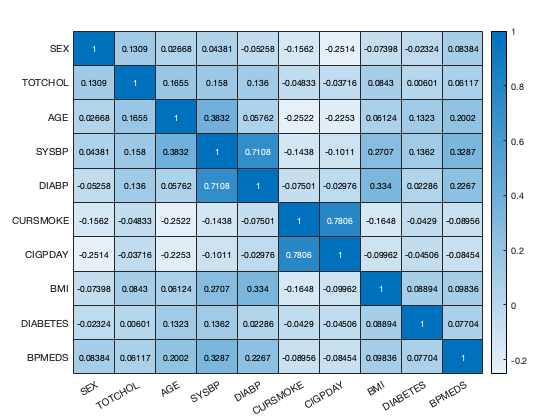

[max_corr_rank, I_rank] = maxk(r_rank,5,"ComparisonMethod","abs");
max_corr_rank = array2table(max_corr_rank,"VariableNames",var_names)
I_rank = array2table(var_names(I_rank),"VariableNames",var_names)

Do the same features have the strongest correlation coefficients?

- Correlation = 0.9509 - CIGPDAY, CURSMOKE

- Correlation = 0.7084 - SYSBP, DIABP

- Correlation = 0.3914 - SYSBP, AGE

While the correlation coefficients are different from the Spearman's rank test, the variables with the strongest linear relationships are the same. 

## Visualizing Correlations

Heatmaps use color-coding to compare data, making it easy to observe variable relationships and patterns. Heatmaps are a useful tool for visualizing pairwise correlations. The `heatmap` command in MATLAB accepts both tables and matrices as inputs. 

Create a heatmap for the pairwise correllations of our ten variables.

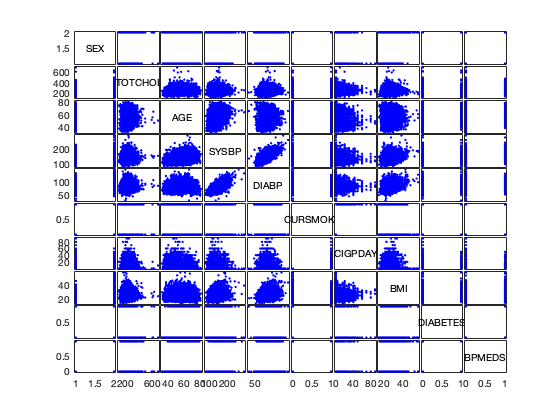

h = heatmap(r);
h.XDisplayLabels = var_names;

h.YDisplayLabels = var_names;

The heatmap makes it very easy to pick out the highest and lowest correlated features.  

Another tool in MATLAB for visualizing raw data correlations is `gplotmatrix`. This command creates a matrix of scatter plots for each variable in the data set against every other variable. 

gplotmatrix(fram_noNaN.Variables,[],[],[],[],[],[],'variable',var_names);